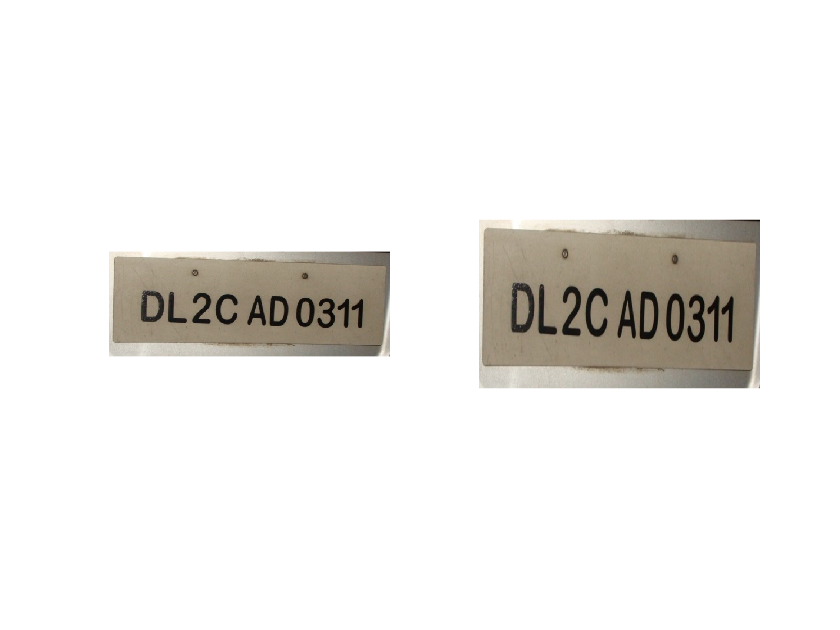


clc
close all;
clear;
load TRAININGSET;
totalLetters=size(TRAIN,2);



% SELECTING THE TEST DATA
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[file,path]=uigetfile({'*.jpg;*.bmp;*.png;*.tif'},'Choose an image');
s=[path,file];
picture=imread(s);
figure
subplot(1,2,1)
imshow(picture)
picture=imresize(picture,[300 500]);
subplot(1,2,2)
imshow(picture)

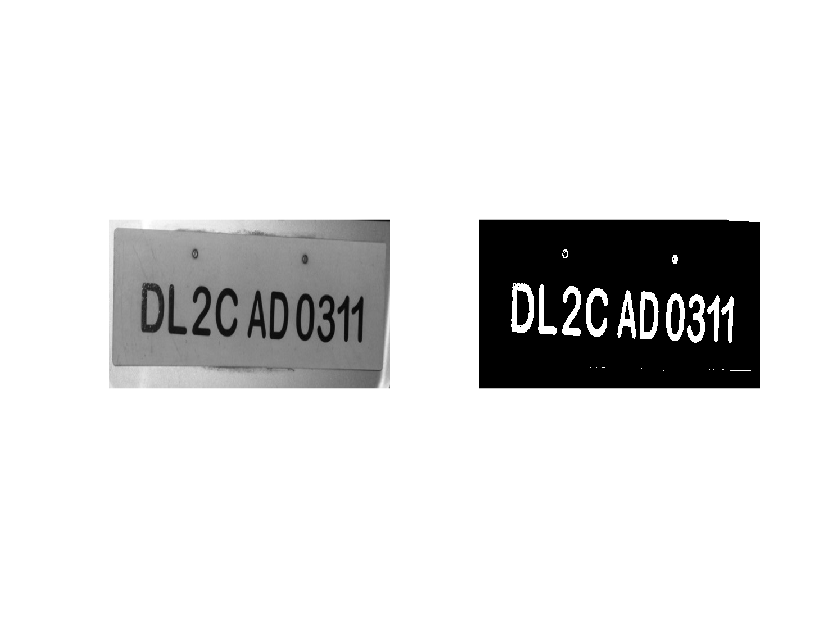



%RGB2GRAY
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
picture=rgb2gray(picture);
figure
subplot(1,2,1)
imshow(picture)

% THRESHOLDIG and CONVERSION TO A BINARY IMAGE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
threshold = graythresh(picture);
picture =~im2bw(picture,threshold);
subplot(1,2,2)
imshow(picture)

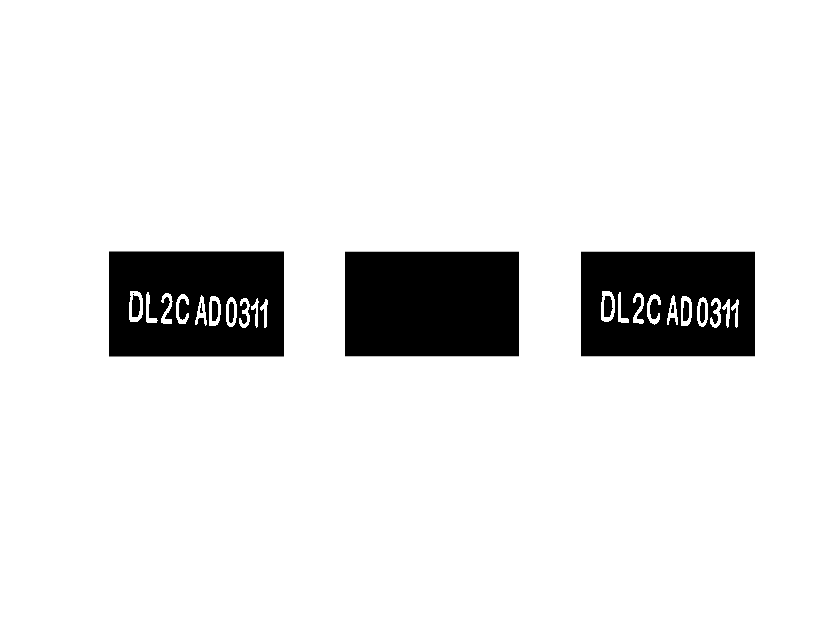




% Removing the small objects and background
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%
figure
% picture = bwareaopen(picture,30); % removes all connected components (objects) that have fewer than 30 pixels from the binary image BW
picture = bwareaopen(picture,200); 
subplot(1,3,1)
imshow(picture)
background=bwareaopen(picture,3000);
subplot(1,3,2)
imshow(background)
picture2=picture-background;
subplot(1,3,3)
imshow(picture2)

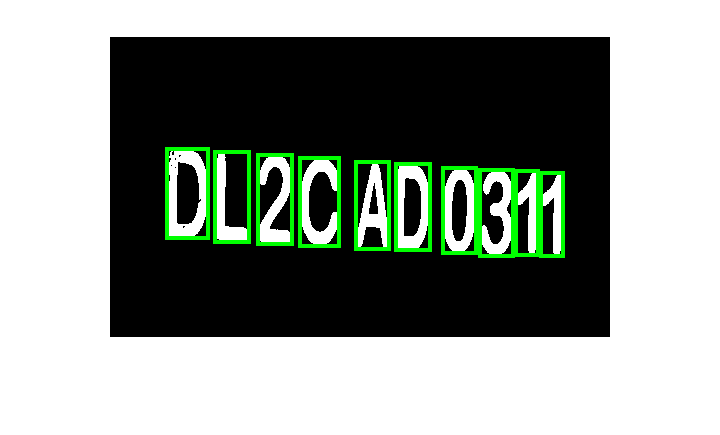

% picture2=bwareaopen(picture2,200);
% subplot(1,4,4)
% imshow(picture2)
%%


% Labeling connected components
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
imshow(picture2)
[L,Ne]=bwlabel(picture2);
propied=regionprops(L,'BoundingBox');
hold on
for n=1:size(propied,1)
    rectangle('Position',propied(n).BoundingBox,'EdgeColor','g','LineWidth',2)
end
hold off

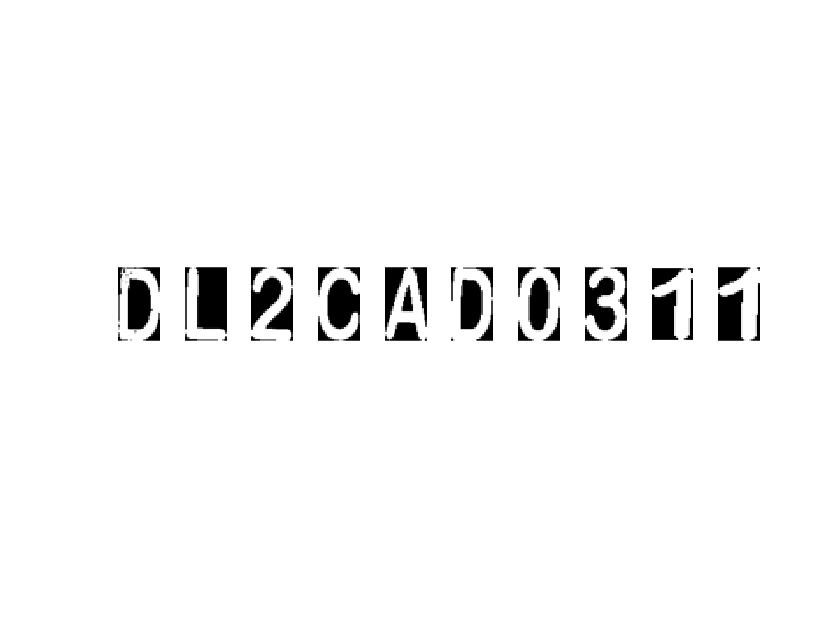




% Decision Making
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
final_output=[];
t=[];
for n=1:Ne
    [r,c] = find(L==n);
    Y=picture2(min(r):max(r),min(c):max(c));
    Y=imresize(Y,[42,24]);
    subplot(1, Ne, n)
    imshow(Y)
    pause(0.2)
    
    
    ro=zeros(1,totalLetters);
    for k=1:totalLetters   
        ro(k)=corr2(TRAIN{1,k},Y);
    end
    [MAXRO,pos]=max(ro);
    if MAXRO>.45
        out=cell2mat(TRAIN(2,pos));       
        final_output=[final_output out];
    end
end




% Printing the plate
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
file = fopen('number_Plate.txt', 'wt');
fprintf(file,'%s\n',final_output);
fclose(file);
winopen('number_Plate.txt')